## Welcome to MATLAB!

The ability to write even the simplest of computer programs is an invalua

ble skill for the modern-day biologist. Today, we'll go through a very quick introduction to MATLAB and simulate a one dimensional random walk.

When you open your MATLAB IDE, you'll find a myriad of windows with varying degrees of complexity. The simplest window is the command window (>>>) which lets us run small snippets of code wether it be for a quick test of a program or just to check the value of a recently defined variable. Everything we will do in this course *could * be done in the command window, but we wouldn't be able to save it and modify it in the future. For programs we may want to open again in the future and modify, we'll write in the script window. Let's test out a few quick commands in the script window (code shown below).

1 + 1

ans = 2

As expected, this returns the value of '2' even though we didn't tell the computer to spit the answer out at us. While it is sometimes useful to have the computer spit out answers at us, we don't *always* want to see the output. To suppress the output of any calculation, we can add a semicolon to the end of the line, as is shown below. 

2 * 3;

To access the the value of the aboe omcputation, we need to give it a variable which the value can be assigned to. Let's do the same calculation as above except this time, we'll assign it to a variable. 

a = 2 * 3; %This output will not show, but will be performed. 
a %This will print. 

a = 6

Notice that I wrote two lines of text within the code window that were not printed. These are prefaced with a percent sign (%) and are called comments. Anything that you place immediately after a percet sign will be completely ignored by MATLAB. When writing new computer code, **always include comments that briefly describe what you are doing!** Not only will this save your self some head-scratching in the future, it will also make life much less miserable for those who may need to look at your code after you've left the lab. Now that we've assigned a variable, we can start to explore some of the more complicated mathematics that MATLAB can perform. Let's explore a few of these. 

%Define a few variables and play with them. 
a = 10; 
b = 2^a; 
c = exp(a / b) + 2E5; 
a

a = 10

b

b = 1024

c

c = 2.0000e+05

Note that MATLAB has specific syntax for some commonly used arithmetic operations such as division and exponentiation. Variables can take all sorts of data types including floating point values (decimals), integers, strings (lines of text), and doubles (we'll talk about this later). Additionally, a variable can have many values of the same type attached to it. MATLAB operates in matrices -- everything that you assign to a variable will be considered a matrix. Let's play around with this. 

%Assign multiple values to a single variable. 
int_variable = [1 5 4 3 5 8];

%Now let's index a few values of each of these vectors. 
int_variable(1) %Should be 1

ans = 1

int_variable(2) %Should be 5

ans = 5

Note that contrary to many other programming languages, **indexing in MATLAB begins at 1, not 0! **Let's try doing a bunch of math to this vector we just created. 

%Let's do some multiplication . 
a = int_variable * 3

a =      3    15    12     9    15    24


b = int_variable / 2

b =     0.5000    2.5000    2.0000    1.5000    2.5000    4.0000


d = int_variable > 4

d =      0     1     0     0     1     1


The last output is interesting. We are applying  a **logical** operator. It is returning a boolean value for if each entry into the array is greater than 4. 

## The Random Walk

As with most things in life, the best way to learn how to program is by jumping into it. Using some of the basic tools in matlab, we will simulate a particle as it goes along a random walk in one dimesion. We'll say that the walk is truly random in that a step to the right is just as likely as a step to the left. This boils down to a simple flip of a fair coin. MATLAB has a built in function to generate such random events. Let's give it a try and see how things go. 

%Use 'rand' to generate a random number between 0 and 1. 
flip_1 = rand()

flip_1 = 0.2553

flip_2 = rand()

flip_2 = 0.0434

flip_3 = rand()

flip_3 = 0.8247

Just by looking at the numbers, we can see that we will probably wander about left and right if we were to simulate this many times. Rather than doing this all by hand, we can take a moment to learn one of the most useful skills in programming -- the loop. Our goal is to flip a coin 10000 times and look at the distribution of values.

%We will first start by defining the number of flips we want to do. 
num_flips = 10000;

%Now we'll define an empty matrix to which we'll add the value for each flip. 
x = [];

%Now we'll draw the random number and add the value to our empty matrix for each flip. 
for i=1:num_flips
    x(i) = rand();
end %Ends the loop. 

There is some important stuff going on in the above lines. The loop is defined by a **for** and an **end **statement. In the above example, we said that  'for i=1:num_flips'. This simply means for each number inbetween 1 and the number assigned to the variable 'num_flips', we will execute whatever commands are below. In this example, it was simply setting the value of an empty vector at that value with whatever the random number generator gave us. 

Now, our x vector is 10 000 entries long and corresponds to the random number that we drew. Let's plot these values as a histogram with 100 bins.

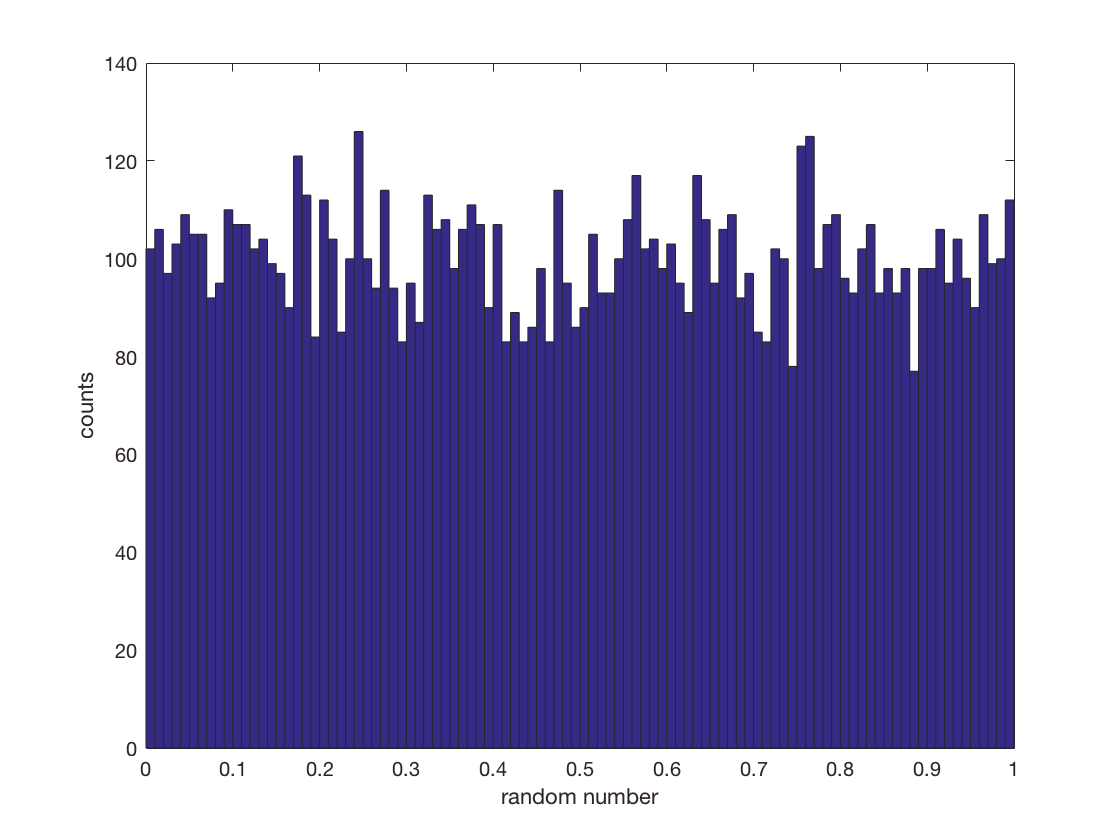

%Plot a histogram of the random numbers. 
hist(x, 100); %It's that easy!

%EVERY plot needs labels! let's add them. 
xlabel('random number')
ylabel('counts')

Well, that distribution certainly looks random to me! For a random walk, we don't care about the exact value of each random number. Rather, we will choose if we will take a step left or right based off of the range that the number is in. In our case, this is simply a step to the right if the number is above 0.5 and a step to the left other wise. Based off the numbers that we just generated, let's see what the distribution of steps looks like.  

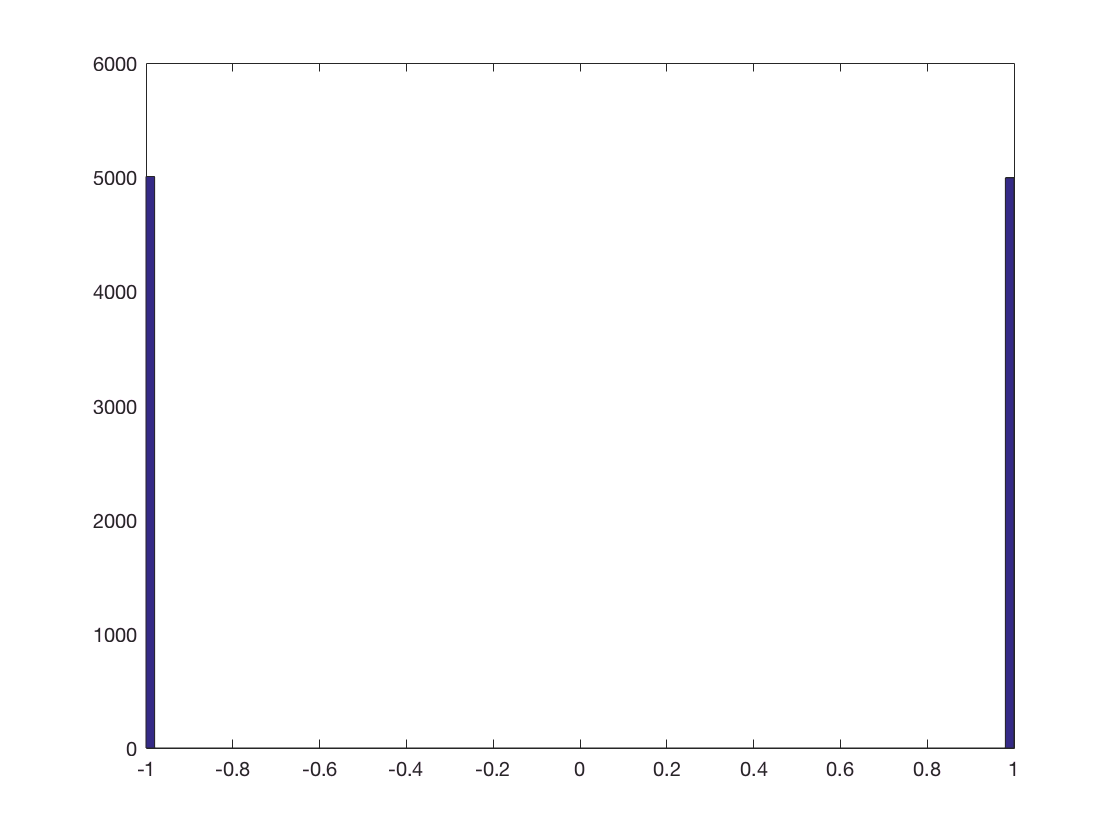

%Apply a logical operator to our vector of values.
for i=1:length(x)
    if x(i) < 0.5;
        x(i) = -1;
    else
        x(i) = 1;
    end
end

%Now we'll generate the histogram that we had above. 
hist(x, 100, c)

By eye, it looks like half the time we took a step right, and half the time we took a step left. Congratulations! just simulated a random walk of a bunch of steps. Let's try simulating this for a bunch of different coin flips ad plot the mean squared displacement.

%Define some parameters. 
n_simulations = 1000;
num_flips = [1 10 100 200 300 500 1000 2000 5000 10000];
%Make an empty vector to which we'll add the mean squared displacement
%of our simulations. 
msd = [];

msd = []

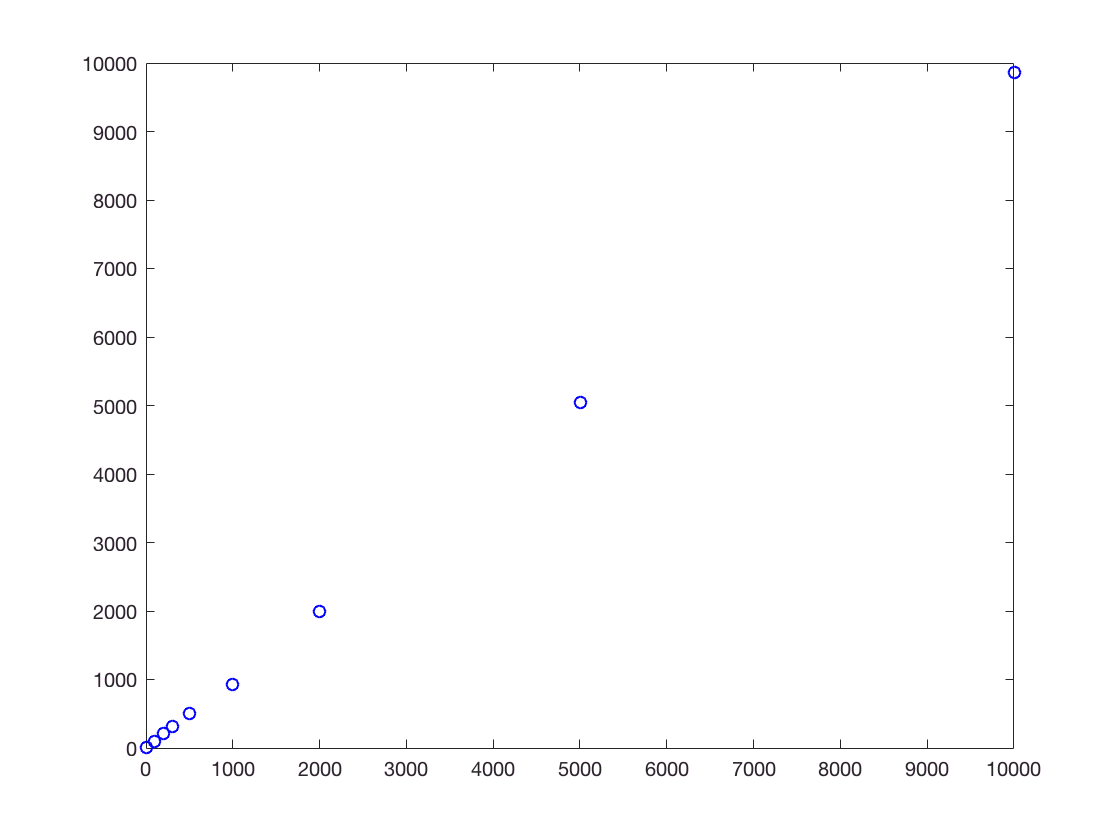


%We'll first iterate through the number of flips. 
for i=1:length(num_flips)
    %Now we'll iterate through each simulation.
    displacements = [];
    for j=1:n_simulations %Can't reuse i
        position = 0;
        for k=1:num_flips(i)
            flip = rand();
            if flip < 0.5
                position = position - 1;
            else
                position = position + 1;
            end
        end
        displacements(j) = position;
        end
     msd(i) = mean(displacements.^2);
        
end
      %Now compute the msd
plot(num_flips, msd, 'bo')